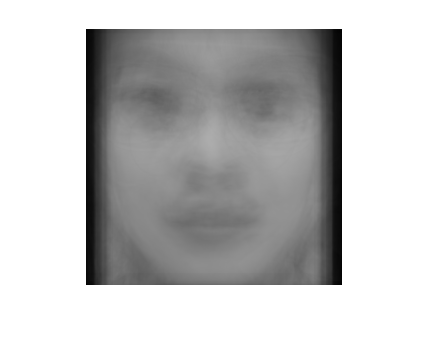

load eigendata.mat;

trans = gen_transformer(images,50);

vis_face(trans.mean,trans);

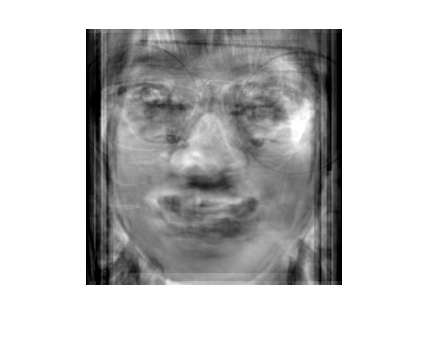


vis_eigen_face(trans,50);

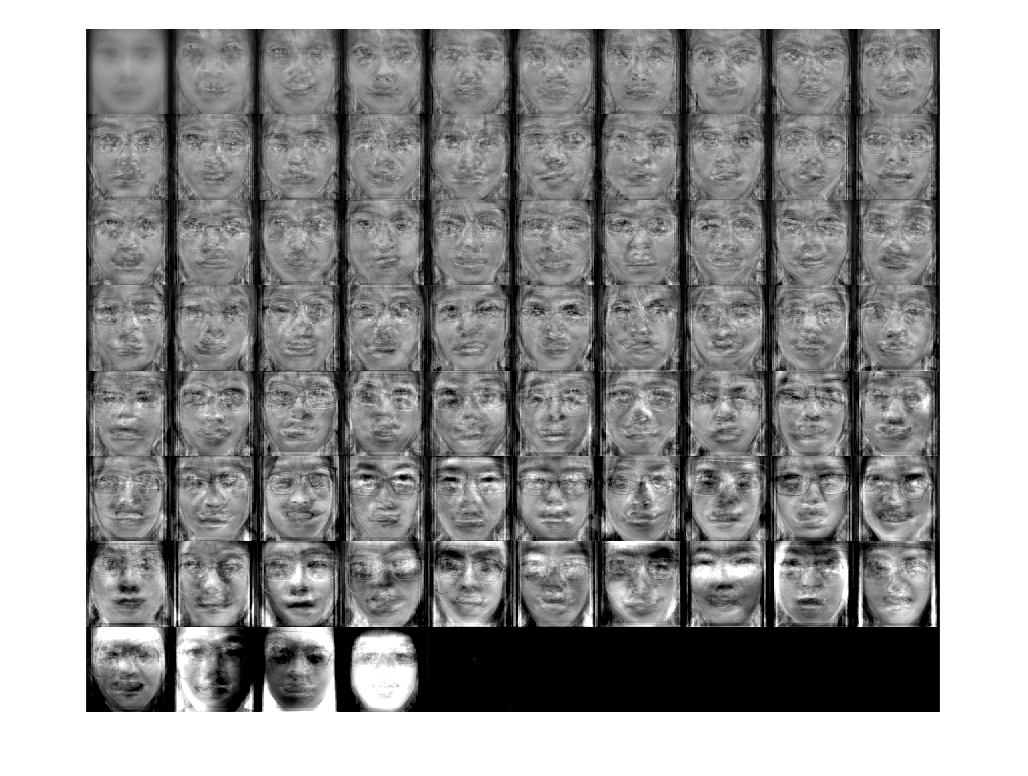


eigen_face_grid = vis_eigen_faces(trans,10);
imshow(eigen_face_grid);

imwrite(eigen_face_grid,'eigen_faces.png');

%classification

N = 50;
frames = eig_frames(A,V,N);
projections = A*frames;

ref_means = zeros(N,15);

for i = 1:15
    acc = zeros(1,N);
    for j=1:5
        acc =  projections((i-1)*5+j,:);
    end
    ref_means(:,i) = (acc)';
end

res_all = zeros(15,75);
for i=1:15
    iv = ref_means(:,i);
    for j=1:75
        jv = projections(j,:)';
        res_all(i,j) = norm(jv-iv,2);
    end
end



function vis_face(vec,trans)
    img = reshape(vec,trans.img_height,trans.img_width);
    imshow(uint8(img));
end

function vis_eigen_face(trans,i)
    vec = trans.eigen_faces(:,i) + trans.mean;
    vis_face(vec,trans);
end

function rst = vis_eigen_faces(trans,N)
    M = ceil(trans.sample_size/N);
    rst = zeros(M*trans.img_height,N*trans.img_width,'uint8');
    for idx = 1:trans.sample_size
       r = floor((idx-1)/N);
       c = mod((idx-1),N);
       offset_r = trans.img_height*r;
       offset_c = trans.img_width*c;
       vec = trans.eigen_faces(:,idx) + trans.mean;
       img = reshape(vec,trans.img_height,trans.img_width);
       rst(offset_r+1:offset_r+trans.img_height,offset_c+1:offset_c+trans.img_width) = img;
    end
end

function frames = eig_frames(A,V,N)
    [sz1,sz2] = size(V);    
    frames = A' * V(:,1:N);
end

function transformer = gen_transformer(images,N)

    % calculate mean
    [i1,i2,i3] = size(images);
    flat_sz = i2*i3;
    sum = zeros(1,flat_sz);
    for i = 1:i1
        img = images(i,:);
        sum = sum+img;
    end
    avg = sum / i1;

    % get mean centered data matrix
    A = zeros(i1,flat_sz);
    for i=1:i1
        img = images(i,:);
        diff = img - avg;
        A(i,:) = diff;
    end
    
    % calclulate eigen faces
    AAT = A * A';
    [V,D] = eig(AAT);
    ef = A' * V;
    
    % write data
    transformer.sample_size = i1;
    transformer.img_height = i2;
    transformer.img_width = i3;
    transformer.A = A;
    transformer.V = V;
    transformer.eigen_faces = ef;
    transformer.mean = avg';
    
end